# Lab 4: Position Control Analysis

**Learning Goals**

- Construct a closed-loop transfer function.

- Plot the step response of a closed-loop transfer function.

- Identify the poles of a closed-loop transfer function.

- Assess the stability of a closed-loop transfer function.

In the previous lab, the motor position PID controller was tuned manually. For simple systems, this method can produce acceptable results. In complex systems, however, manual tuning can become very challenging. Mathematical models offer insight into the system dynamics, leading to improved controller design. In this lab, you will construct and analyze a model of the position PID controller.

## Closed-loop transfer function

In this section, you will derive the closed-loop transfer function for the DC motor position PID controller.

### DC motor position transfer function

A (brushed) DC motor works by conducting a current through an armature that can rotate freely. The fixed brushes transmit the current to the rotating commutators. The current flowing through the armature passes through a magnetic field generated by the stator magnets, resulting in a Lorentz force in the perpendicular direction. The two sides of the armature produce forces in opposite directions, resulting in a net torque on the rotor $T$. If sufficient torque is applied, the shaft rotates, changing the angular position $\theta$.

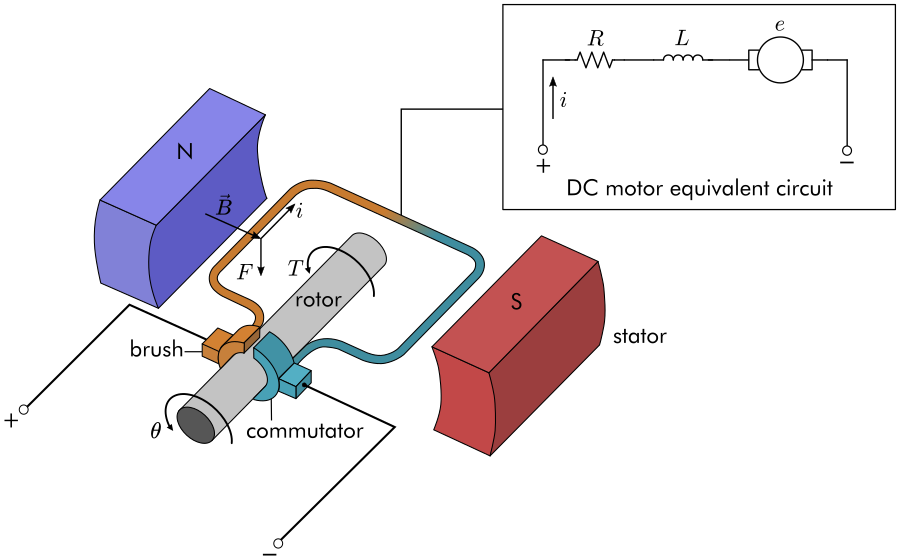

*Brushed DC motor schematic. A net torque *$T$ *is generated on the armature by Lorentz forces. In the electrical domain, the motor is represented by a series of three circuit elements.*

The position transfer function of a DC motor (with certain modeling assumptions) can be analytically derived to be 


$$G(s)= \frac{\Theta(s)}{V(s)} = \frac{k_m}{s(LJs^2 + (RJ+LB)s + BR + k_mk_e)}$$


where

- $\Theta(s)$: the Laplace transform of the shaft position

- $V(s)$: the Laplace transform of the input voltage

- $L$: inductance (H)

- $R$: resistance ($\Omega$)

- $J$: moment of inertia (kg$\cdot$m$^2$)

- $k_m$: motor torque constant (N$\cdot$m$\cdot$s)

- $k_e$: electromotive force constant (V/(rad/s))

- $B$: coefficient of friction (N$\cdot$m/(rad/s))

In many practical cases, the values of the parameters are not known. While it is possible to measure the values of the physical constants, a simpler approach is to identify the coefficients of the transfer function. The coefficients can be estimated from the step response of the plant. For the virtual DC motor, the transfer function can be estimated using the [Model Linearizer](https://www.mathworks.com/help/slcontrol/ug/linearize-simulink-model.html). With the default parameters, the virtual DC motor can be approximated by


$$G = \frac{113.7}{s(s +  3.398)}$$


Note that the highest order term has been neglected because its contribution is small relative to the other terms.

**Task 1. **Define the DC motor transfer function $G$ in MATLAB using [`tf`](https://www.mathworks.com/help/control/ref/tf.html). The `tf `function has the syntax

     `tf(num,denom)`

where `num` represents the coefficients of the numerator and `denom` represents those of the denominator in descending order. You will need to include a placeholder value of 0 in the denominator coefficient vector to account for the constant term.

% Write code to define G here
G = tf([0 0 113.7],[1 3.398 0])

**Task 2. **To validate the transfer function model, you can compare it to the virtual DC motor model. To do so, construct the model shown below.

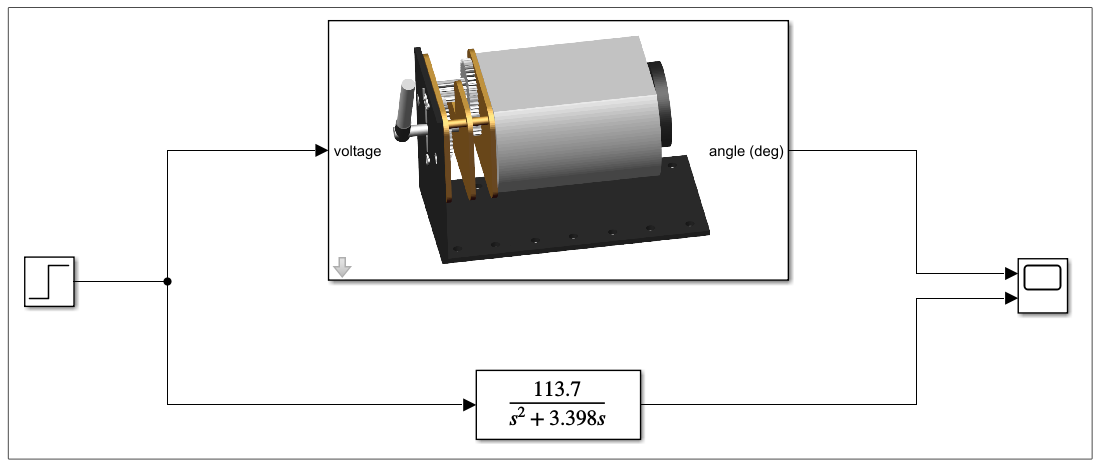

- Open [`DCMotor.slx`](matlab: open_system("DCMotor.slx")) and save the model to a new file. Remove any unnecessary blocks.

- Double-click the motor image to show the dialog parameters. Set the virtual DC motor parameters to **B = 0.028 **Nm/(rad/s), **K = 0.05 **V/(rad/s),** L = 0.1 **H, **R = 0.25** Ohm, **Pendulum mass = 0.15 **Kg, **Pendulum length = 0.015 **m, and **Sensor noise gain = 0**. Also, turn voltage saturation off by unchecking the **Use voltage saturation** checkbox. 

- Add a [Transfer Fcn](https://www.mathworks.com/help/simulink/slref/transferfcn.html) block with the numerator and denominator set to match the transfer function you defined in the previous task.

- Add a [Step](https://www.mathworks.com/help/simulink/slref/step.html) block with Step time: 0, Initial value: 0, Final value: 1, Sample time: 0.

- Add a [Scope](https://www.mathworks.com/help/simulink/slref/scope.html) block so that you can observe the result.

Run the model and view the output in the scope. If correct, the output of the transfer function should be nearly identical to the output of the virtual DC motor.

### Define the closed-loop transfer function

With the transfer function of the plant identified, the closed-loop transfer function can be generated. You can derive this from the block diagram.

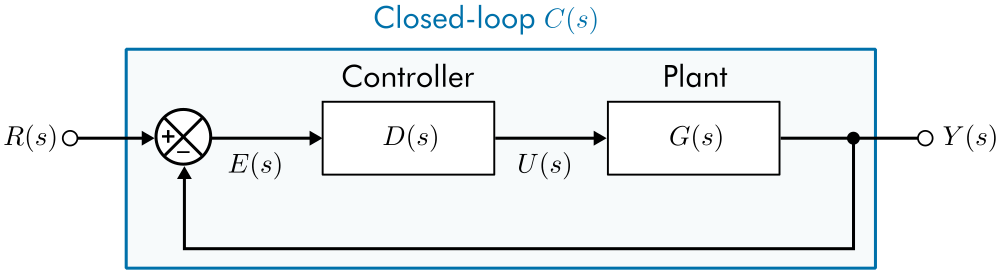

*Block diagram for the PID control feedback loop. The closed-loop transfer function *$C(s)$*encapsulates the entire feedback loop. The reference value denoted *$R(s)$* is the input of *$C$* and its output is *$Y(s)$*. *

The closed-loop transfer function $C$ can be easily derived from the block diagram to be


$$C = \frac{Y}{R} = \frac{DG}{1+DG}$$


The plant transfer function $G$ was identified in the previous section. The controller transfer function $D$ must also be known. A PID controller computes the control signal as


$$u(t) = k_p e + k_i \int_0^\tau e(\tau) d \tau + k_d \frac{de}{dt}$$


You can compute the controller transfer function $D$ by taking the Laplace transform and then solving for the ratio of the input error, $E(s)$, to the output control signal, $U(s)$:


$$D(s) = \frac{U(s)}{E(s)} = k_p + \frac{k_i}{s} + k_d s$$


**Task 3. **With the parameters $k_p = 1$, $k_i = 0.1$, and $k_d = 0.1$, compute the PID transfer function $D$.

**Hint**: define the transfer function $s$ using `s = tf('s')`. Then, use the variable $s$ with standard arithmetic operations to define $D$. Here is an example of this process to define $R(s) = \frac{1}{s^2} - 0.3s$:

% Write your code to define D here
kp = 1;
ki = 0.1;
kd = 0.1;

s = tf('s');
D = kp + ki/s + kd*s

**Task 4. **Compute the closed-loop transfer function $C$ for the PID position control of the DC motor using the transfer functions $G$ and $D$ you defined in the previous two tasks.

**Note:** It is possible to compute the closed-loop transfer function as $C = DG/(1+DG)$. However, this formula will generate an unnecessarily complicated expression. Instead, use the [`feedback`](https://www.mathworks.com/help/control/ref/lti.feedback.html) function. The syntax for `feedback` is

- `sys1`: the feedforward transfer function

- `sys2`: the feedback transfer function 

- `sys:` the transfer function of the closed-loop system

These variables can be more easily understood in a block diagram.

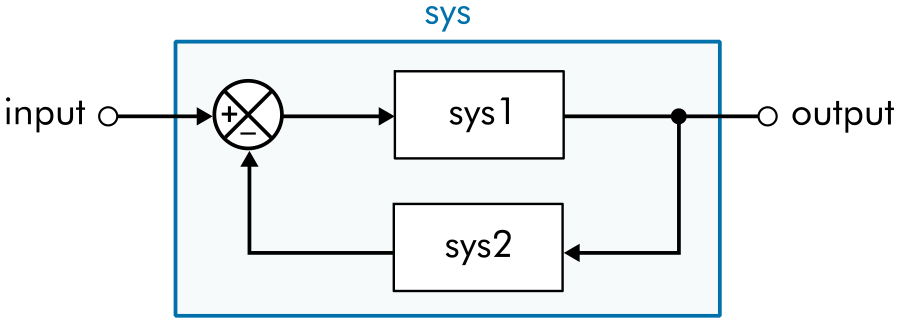

*Block diagram explanation of the syntax for the *`feedback`* function*

For this model, the feedback transfer function `sys2` should be set to `1`. 

% Use "feedback" to define C here
C = feedback(D*G,1)

**Task 5. **Compute and plot the step response of the closed-loop transfer function $C$ using [`step`](https://www.mathworks.com/help/control/ref/lti.step.html). If correct, your answer should appear as shown below.

% Write your code here
step(C)

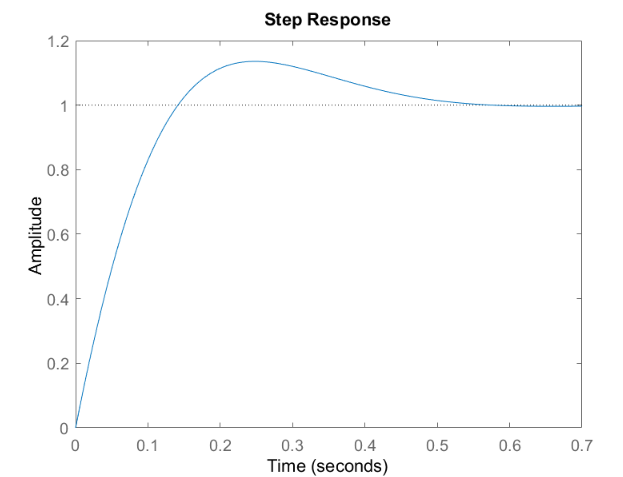

*Step response of the closed-loop transfer function with *$k_p = 1$*, *$k_i = 0.1$*, and *$k_d = 0.1$*.*

**Task 6. **Based on the step response you observed in **Task 5**, do you think the closed-loop transfer function is stable?

task6 = "Yes"

## Stability of the feedback controller

The **poles** of a rational transfer function occur where the denominator is zero. Consider a transfer function in factored form:

    
$$G(s) = K \frac{ (s-z_1)(s-z_2) \ldots (s-z_m) }{ (s-p_1)(s-p_2) \ldots (s-p_n)}$$


The poles are $p_1$, $p_2$, $\ldots$, $p_n$. Recall that the poles of a transfer function determine its general behavior and stability.

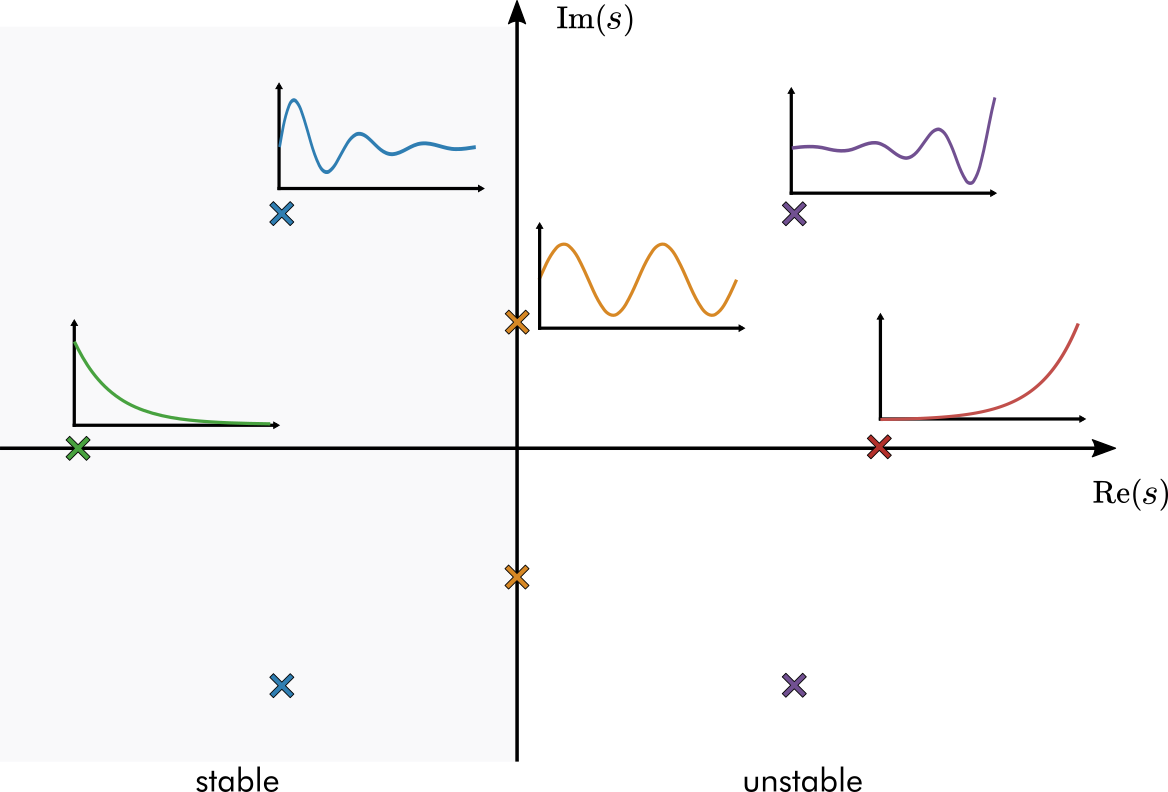

* Impulse responses characterized by the position of poles in the complex *$s$*-plane. Poles in the left-half plane (where *$\text{Re}(p) < 0$*) are stable.*

If all the poles of a transfer function lie in the left-half plane, then the transfer function is stable. In this section, you will assess the stability of the feedback controller by examining the poles of its closed-loop transfer function.

**Task 7. **Compute the poles of the closed-loop transfer function $C$. Computing the poles by hand is challenging. Instead, use the [`pole`](https://www.mathworks.com/help/control/ref/lti.pole.html) function.

% Write your code here
task7 = pole(C)

**Task 8**. Based on the poles computed in **Task 7**, is the closed-loop transfer function stable?

task8 = "Yes"

**Task 9**. It can be helpful to visualize the poles of the system in the complex plane. Use the [`pzmap`](https://www.mathworks.com/help/control/ref/lti.pzmap.html) function to plot the poles. Also, set the real and imaginary axis limits to `[-10,10]` using [`axis`](https://www.mathworks.com/help/matlab/ref/axis.html) as:

% Write your code here
pzmap(C)
axis([-10 10 -10 10])